## Spike detection and spike rate analysis week 2, tutorial 2

In this live script we will read spike data into matlab with spike times aligned to auditory stimulus, recreate a raster plot aligned to stimulus and produce a Peristimulus time histogram (PSTH)

Tutorial using data from [https://github.com/yannikbauer/Raster_PSTH_SDF](https://github.com/yannikbauer/Raster_PSTH_SDF)

clc
close all
clear

# Part 1 - Read the spike data 

1. load the electrical recordings

load('sptimes.mat')


2. verify what kind of variable is contained in the opened .mat file

class(sptimes)

**Inspect the data**

A. What is the data size?

datasize = 

% datasize = ;  % $$$

B. What is the size of the first and second cell in sptimes?

Use indexing of the right cell with { }

disp() % $$$
disp() % $$$


C. Try to create a vector with two columns:

one column has the values of the first cell; the second column has values of the second cell

TIP: use [ ] to concatenate two single column vectors; 

TIP2: **[a, b]** and **[a; b]** result in different matrices

% vector = ; % $$$


D. Why can't the two rows be side to side? How can the data be aggregated into a single vector?

Write your answer below:

% Answer

% 

E. What is the size of each cell in sptimes?

TIP: initialize an empty variable and add the length of each cell there

scells = []; % vector where all sizes of each cell should be stored

for c = 1:length(sptimes)
%     scells(c) = ; % $$$
end
disp(scells)

F. What is the mean of spikes per trial?

% avg_spikeptrial =  % $$$

# Part 2 - Create a raster plot of the spikes 

**Warm up** - Plot the first line of a raster plot (spikes in trial y) at the position y = trial

trial = 10;
figure;
plot(sptimes{trial}, trial, 'g.', 'MarkerSize', 10)


3. open a figure and prepare a "subplot" with two panels stacked

figure('Units','normalized','Position',[0 0 .5 1])
ax = subplot(2,1,1); hold on

4. For each trial, plot dots at every x with a spike. Keep one line for each trial

TIP: use for loops across all trials

TIP2: for the position of each spike in time (x) you'll need a y value. Which value should that be?

5. Use pause() to create a figure that is slowly filled up

% ntrials = ; % $$$

for itrial = 1:ntrials

%      xspikes           =    ;   % Get all spikes of respective trial % $$$
%      yspikes      	   =    ;   % y values(trials) % $$$

    % plot % $$$
    % pause % $$$
%     
end
% set figure limits to last trial and to end of the recording window
ax.XLim             = [-.2 .3];
ax.YLim             = [0 ntrials];
ax.XTick            = [0 .2];
ax.XLabel.String  	= 'Time [s]';
ax.YLabel.String  	= 'Trials';


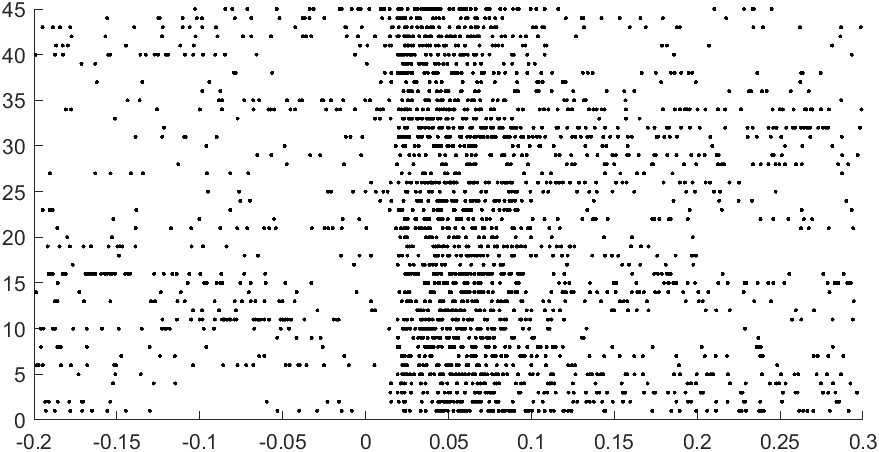

# Part 3 - Create a PSTH 

6 Add all spike times to a single vector

TIP: use a similar notation as before with [ ]. 

%% Peristimulus time histogram (PSTH)

% intialize vector for all spikes
allspike = [];

% loop across all cells and get the values into a single column vector
for iTrial = 1:length(sptimes)
     % Concatenate spikes of current trial to allspike
%       allspike             = ;   % $$$
end

7. Based on the spike times what is the minimum time point before the stimulus and the maximum after

TIP: use the functions *min* and *max *

% min_t = % $$$
% max_t = % $$$

8. Create a histogram with all spike timings and by segmenting data into nbins

A. set nbins to the desired number of bins

B: set the length of each trial (see above min and max times; trials are not 1sec long)

C. get the length of each trial in msecs

******histogram* makes the histogram and automatically plots it

% nbins               = ; % $$$
% trilength_secs      = % $$$
% trilength_msec      = % $$$


ax                  = subplot(2,1,2);
h                   = histogram(allspike,nbins);
h.FaceColor         = 'k';

% ___________ set up axis, color and scaling of the figure ___________ %
mVal                = max(h.Values)+round(max(h.Values)*.1);
ax.XLim             = [-.2 .3];
ax.YLim             = [0 mVal];
ax.XTick            = [0 .2];
ax.XLabel.String  	= 'Time [s]';

% Fix the y axis to represent spikes/sec
slength             = trilength_msec;                                  % Length of signal trace [ms]
bdur                = slength/nbins;                        % Bin duration in [ms]
nobins              = 1000/bdur;                            % No of bins/sec
for iLab = 1:length(ax.YTickLabel)
    lab             = str2num(ax.YTickLabel{iLab});
    conv            = (lab / length(sptimes)) * nobins; 	% Convert to [Hz]: avg spike count * bins/sec
    newlabel{iLab}  = num2str(round(conv));                 % Change YLabel
end
ax.YTickLabel       = newlabel;
ax.YLabel.String  	= 'Firing Rate [Hz]';

# Final Question 

9a. What is approximately the baseline firing rate when there's no stimulus?

% Answer:

%

9b. What is approximately the increase in the firing rate from baseline to stimulus? (answer in fold increase in firing rate)

% Answer:

%

# Review:

You should have values and answers for

Part 1 - A,  B, C, D, E, F

Part 2 - 4, 5 should produce the raster plot of the spikes

Part 3 - 6, 7, 8 should produce a histogram with firing rate x time

Final Question - 9a, 9b